# Nye 1960 Glacier Height Evolution

### Anna Redanz and Autumn Toms

### Introduction

The purpose of this project is to study the impact of climate on glaciers through modeling the kinematics and mechanics of ice flow. It is important because glaciers are sensitive to slight changes in climate. Past climate changes can be inferred based on how glaciers molded landscapes and changed vegetation over time. To understand these changes, we need to understand how glaciers respond to changes in climate. Climate can change precipitation patterns or rate of snowmelt, which can increase or decrease the height of a glacier, respectively. We aim to explore part of the model in Nye (1960) to discover how seasonal accumulation affects glacier height.

The model described in Nye (1960) is a one-dimensional flow system. Two-dimensional and three-dimensional flow system models are much more complex but represent a more accurate picture of glacial change with time. One current model used to investigate the impacts of accumulation on glaciers is ALPINE3D. ALPINE 3D considers the impact of many factors such as snowpack, snow drift, and runoff over a three-dimensional surface. Our model only considers accumulation, so ALPINE3D would model real-life scenarios significantly more accurately.

### Equations

This model is based on the concept that a glacier is a one-dimensional flow system which is continuously receiving or losing new material. Glacier thickness changes as a result of accumulation, where positive accumulation is addition of ice due to snowfall or avalanche, and negative accumulation is the melting or evaporation of ice from the surface. Assuming that there is no change in ice volume, the ice flow (q) can be modeled in the following partial differential equation (PDE), where q is ice flow, h is glacier height (m), and a is surface accumulation (ms). 

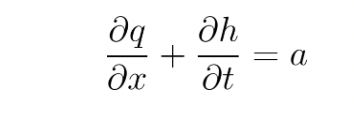

Ice velocity (u) is calculated by the following equation. 

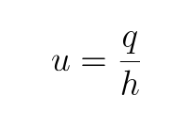

Substitute q = uh into the flow PDE, giving us the following advection equation.

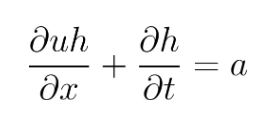

We solve for velocity using the following equation.

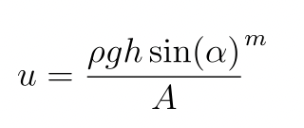

Density (⍴) is 917 kg/m^3, gravity (g) is 9.81 m/s^2, the power law exponent (m) is 3, and the rate factor of deformability (A) is 7*10^6 (s/m)^(1/3). Surface slope (⍺) is calculated as a function of (x, t) downhill in the x direction. 

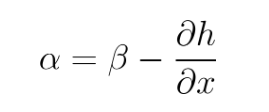

Slope of inclination (𝛽) is 1.510-3. We assume that changes in thickness with respect to space are negligible compared to bed slope, so we simplify the equation to ⍺ = 𝛽.

### Numerical methods

We use the upwind forward Euler numerical method to solve this advection PDE. We use a small Δt of one day and Δx of 100 m to ensure stability. By discretizing the flow equation above using the upwind method, the marching equation is as follows.

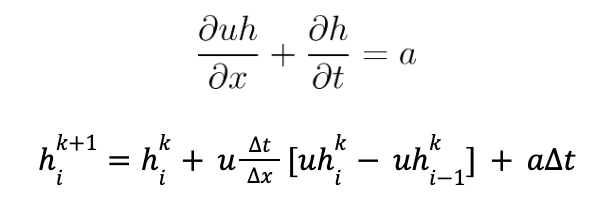 

Based on Nye (1960), as assume flux is set by the bed topography. At the beginning of the glacier, where ice meets land, we place a Neumann boundary condition stating that dhdx=0. We assume that at the top of the glacier, the derivative of height with respect to space is zero because the change in height with space is zero where the glacier meets land. The initial condition for thickness is h(x=0) = 5,000 m. We assume the slope of the glacier is linear; therefore, at the end of the glacier, where the glacier meets water, we placed a Dirichlet boundary condition stating that h=0. 

% Forward Euler

year = 24*365*60*60;    %year in seconds
month = year/12;        %month in seconds
day = 24*60*60;         % seconds in a day
dt = day;
tf = 10*year;           %time frame and also time final running 10 years
nt = tf/dt;             %number of time steps
t = linspace(0,tf,nt);
a_init = .000005;       %m/s

a_rate = a_init.*sin((t)); 
a_rate2 = a_init.*3*sin((t.*8)); 



H = Up_euler(-.000005, "Constant Negative");

len =      2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51


a_rate = -5.0000e-06

div = 365

H = Up_euler(.000005, "Constant Positive");

len =      2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51


a_rate = 5.0000e-06

div = 365


H = Up_euler_sin(a_rate, "Functions of Low Frequency sin Varying");

len =      2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51


a_rate = 	1.0e+-5 *

         0   -0.4997   -0.0346    0.4973    0.0690   -0.4925   -0.1031    0.4854    0.1367   -0.4759   -0.1696    0.4642    0.2018   -0.4502   -0.2329    0.4341    0.2630   -0.4159   -0.2918    0.3957    0.3192   -0.3736   -0.3450    0.3497    0.3692   -0.3242   -0.3917    0.2971    0.4122   -0.2685   -0.4308    0.2387    0.4473   -0.2077   -0.4617    0.1758    0.4739   -0.1430   -0.4838    0.1095    0.4914   -0.0755   -0.4966    0.0411    0.4994   -0.0065   -0.4999   -0.0281    0.4979    0.0625


div = 365

H = Up_euler_sin(a_rate2, "Functions of High Frequency sin Varying");

len =      2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51


a_rate = 	1.0e+-4 *

         0    0.0410    0.0789    0.1108    0.1342    0.1474    0.1494    0.1400    0.1199    0.0907    0.0546    0.0143   -0.0271   -0.0664   -0.1006   -0.1272   -0.1441   -0.1500   -0.1445   -0.1279   -0.1017   -0.0676   -0.0284    0.0129    0.0533    0.0896    0.1191    0.1395    0.1493    0.1477    0.1348    0.1117    0.0801    0.0423    0.0014   -0.0397   -0.0777   -0.1098   -0.1336   -0.1471   -0.1495   -0.1405   -0.1207   -0.0918   -0.0559   -0.0157    0.0257    0.0651    0.0996    0.1265


div = 365

len =      2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51


a_rate = 	1.0e+09 *

         0   -0.0009   -0.0017   -0.0026   -0.0035   -0.0043   -0.0052   -0.0060   -0.0069   -0.0078   -0.0086   -0.0095   -0.0104   -0.0112   -0.0121   -0.0130   -0.0138   -0.0147   -0.0156   -0.0164   -0.0173   -0.0181   -0.0190   -0.0199   -0.0207   -0.0216   -0.0225   -0.0233   -0.0242   -0.0251   -0.0259   -0.0268   -0.0277   -0.0285   -0.0294   -0.0302   -0.0311   -0.0320   -0.0328   -0.0337   -0.0346   -0.0354   -0.0363   -0.0372   -0.0380   -0.0389   -0.0398   -0.0406   -0.0415   -0.0423


div = 365



% accumulation, we will run accumulation using 2 constant cases, one
% positive and one negative, and 2 with seasonal changes


function [H] = Up_euler(a, a_title)

%parameters
rho = 917;              % ice density kg/m^3
g = 9.81;               % gravity (m/s^2)
m = 3;                  % constant from autumns last paper
A = 7*10^6;             % basal roughness, ask for value
beta = 1.5*10^-3;       %slope
alpha = beta;           %bed slope--> 

%time
year = 24*365*60*60;%year in seconds
month = year/12;    %month in seconds
day = 24*60*60;     % seconds in a day
dt = day;
tf = 10*year;       %time frame and also time final running 10 years
nt = tf/dt;         %number of time steps
t = linspace(0,tf,nt);

%grid spacing
dx = 100;                   %meters, size of grid step
glacier_length = 60000;     %length of our mountain glacier
x = linspace(0, glacier_length,dx);
nx = length(x);

%H initial!
len = 2:nx
h_init = 5000; %m
H = nan(nx,nt); 
H(2:end,1) = h_init - len.*(h_init/nx);  %this makes our glacier height linearly decline to 0!
H(1,1) = h_init; 

%accumulation
a_rate = a

for k = 1:nt-1

    %calulating U for each time step
    u = ((rho.*g.*H(:,k).*sin((alpha))).^m)./(A.^m);

    %setting up the M matrix
    M = spdiags([u*dt/dx.*ones(nx,1),1-(u*dt/dx).*ones(nx,1)],-1:0,nx,nx);
   
    %boundary conditions
    
    M(end,end) = 1;
    M(end,end-1) = 0;
    M(1,1) = 0;
    M(1,2) = 1;

    H(:,k+1) = M*H(:,k)+a_rate*dt;
    %-a*v*dt
end
div = nt/10
%plot(t, H)
H = flip(H ,1);
figure
plot(x, H(:,div),'r','LineWidth', 1.25)
hold on
plot(x, H(:,div*2),'color',"#D95319",'LineWidth', 1.25)
plot(x, H(:,div*3),'color',"#EDB120",'LineWidth', 1.25)
plot(x, H(:,div*4),'y','LineWidth', 1.25)
plot(x, H(:,div*5),'g','LineWidth', 1.25)
plot(x, H(:,div*5),'color',"#77AC30",'LineWidth', 1.25)
plot(x, H(:,div*6),'c','LineWidth', 1.25)
plot(x, H(:,div*7),'Color',	"#4DBEEE",'LineWidth', 1.25)
plot(x, H(:,div*8),'b','LineWidth', 1.25)
plot(x, H(:,div*9),'color',"#7E2F8E",'LineWidth', 1.25)
plot(x, H(:,div*10),'m','LineWidth', 1.25)
xlabel('x (m)')
ylabel('Glacier Height (m)')
title('Advection With ' +a_title+ ' Accumuation' )
legend('year 0','year 1','year 2','year 3','year 4','year 5','year 6','year 7','year 8','year 9','year 10', 'location','northwest')
hold off

end


function [H] = Up_euler_sin(a, a_title)

%parameters
rho = 917;           % ice density kg/m^3
g = 9.81;            % gravity (m/s^2)
m = 3;               % constant from autumns last paper
A = 7*10^6;          % basal roughness, ask for value
beta = 1.5*10^-3;    %slope
alpha = beta;        %bed slope--> 

%time
year = 24*365*60*60;    %year in seconds
month = year/12;        %month in seconds
day = 24*60*60;         % seconds in a day
dt = day;
tf = 10*year;           %time frame and also time final running 10 years
nt = tf/dt;             %number of time steps
t = linspace(0,tf,nt);

%grid spacing
dx = 100;               %meters, size of grid step
glacier_length = 60000; %length of our mountain glacier
x = linspace(0, glacier_length,dx);
nx = length(x);

%H initial!
len = 2:nx
h_init = 5000; %m
H = nan(nx,nt); 
H(2:end,1) = h_init - len.*(h_init/nx);  %this makes our glacier height linearly decline to 0!
H(1,1) = h_init; 

%accumulation
a_rate = a

for k = 1:nt-1

    %calulating U for each time step
    u = ((rho.*g.*H(:,k).*sin((alpha))).^m)./(A.^m);

    %setting up the M matrix
    M = spdiags([u*dt/dx.*ones(nx,1),1-(u*dt/dx).*ones(nx,1)],-1:0,nx,nx);
    %boundary conditions
    %height goes to 0 at the end of the glacier
  
    %set u value each time from last u value calculated
    
    M(end,end) = 1;
    M(end,end-1) = 0;
    M(1,1) = 0;
    M(1,2) = 1;

    H(:,k+1) = M*H(:,k)+a_rate(k)*dt;
    
end
div = nt/10

H = flip(H ,1);

%plotting

figure
plot(x, H(:,div),'r','LineWidth', 1.25)
hold on
plot(x, H(:,div*2),'color',"#D95319",'LineWidth', 1.25)
plot(x, H(:,div*3),'color',"#EDB120",'LineWidth', 1.25)
plot(x, H(:,div*4),'y','LineWidth', 1.25)
plot(x, H(:,div*5),'g','LineWidth', 1.25)
plot(x, H(:,div*5),'color',"#77AC30",'LineWidth', 1.25)
plot(x, H(:,div*6),'c','LineWidth', 1.25)
plot(x, H(:,div*7),'Color',	"#4DBEEE",'LineWidth', 1.25)
plot(x, H(:,div*8),'b','LineWidth', 1.25)
plot(x, H(:,div*9),'color',"#7E2F8E",'LineWidth', 1.25)
plot(x, H(:,div*10),'m','LineWidth', 1.25)
xlabel('x (m)')
ylabel('Glacier Height (m)')
title('Advection With ' +a_title+ ' Accumuation' )
legend('year 0','year 1','year 2','year 3','year 4','year 5','year 6','year 7','year 8','year 9','year 10','location','northwest')
hold off


end

### Results

The simulations we perform on this model test how varying accumulation functions impact ice thickness with time. In the first two simulations, accumulation is held constant over the timescale. The purpose is to simulate how constant accumulation rate and constant ablation rate change glacier thickness with time. Our first simulation was run with a positive constant accumulation rate over a ten year timescale. This yielded predictable results where the height of the glacier constantly increases with time. The opposite results occurred when the simulation was run with a constant negative accumulation rate, showing a decrease in height with time. This mimicked how ablation would occur in a real glacier if there were no other seasonal factors. 

The remaining two simulations include a sinusoidal accumulation rate: one of a lower frequency and the other of a higher frequency. Sine functions were chosen to represent seasonal accumulation changes impact glacier thickness. The first simulation is based on a low frequency sine wave which simulates longer snow events occurring less frequently. The second sine wave graph aims to simulate snow events happening at higher frequency and lasting shorter periods of time. Both graphs show very similar results, leading us to conclude that within our model frequency and duration of accumulation are not influential factors in overall glacier evolution, as long as total accumulation rate is constant.

Comparing our results to other published work, our model shows a similar relationship between height and distance, as those shown in Fig 7 and 8 of Samsonov et al. 2021. While their figures are synthetic-aperture-radar-derived from an existing glacier, our linear assumed results do match with their plots of real glacier height profiles. 

Our model is very sensitive to changes in dt and dx. We found a thin window of stability by decreasing x, increasing t, and increasing velocity (u). Modeling this equation was complicated because the velocity is dependent on height, so it changes with every timestep as height changes. Because velocity is height dependent, using a small initial height cause our Courant number to increase and become unstable. The courant number is defined in the following equation.

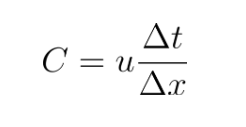

We increased the size of our glacier beyond that of a typical alpine glacier to a length of 60,000 m and a height initial condition of 5,000 m. When calculating the Courant number, to account for velocity changing at every time step, we moved the definition of the courant number into the matrix and redefined the matrix within every loop.

The model we created showed how glacier evolution is dependent on the amount and rate of accumulation. With temperatures increasing due to climate change, accumulation rate could decrease. Therefore, modeling glacial response to processes such as sea level rise and sea surface temperature increases may be accurate predictors of future conditions due to climate change.

This model can be improved by changing how seasonal changes in accumulation are modeled. While a sin function does approximate the seasonal fluctuations of snowfall, it doesn't account for decreasing or increasing snowfall rates from year to year. We also assume a linear slope from our peak height to the end of the glacier. This is not an accurate reflection of a real life glacier. Including topography on an otherwise straight line would improve this model. We also neglect processes that influence glacier height over time, including air temperature increases, sea surface temperature increases, and dry seasons. Additionally, because our courant number changes with height, our model could potentially become diffusive. This potentially diffusive behavior was the trade off that was required to have a velocity that varies in space rather than assuming a constant velocity. Another simplifying assumption that we made was that ⍺ = 𝛽 rather than accounting for change in height. The removal of this assumption in future models could increase the accuracy.

### References

“Alpine 3D.” *SLF*, https://www.slf.ch/en/services-and-products/alpine-3d.html. 

Nye John Frederick. 1960, The response of glaciers and ice-sheets to seasonal and climatic changes. Proc. R. Soc. Lond. A 256: 559–584. [http://doi.org/10.1098/rspa.1960.0127](http://doi.org/10.1098/rspa.1960.0127)

Samsonov, Sergey, et al. “Measuring the State and Temporal Evolution of Glaciers in Alaska and Yukon Using Synthetic-Aperture-Radar-Derived (SAR-Derived) 3D Time Series of Glacier Surface Flow.” *The Cryosphere*, vol. 15, no. 9, 2021, pp. 4221–4239., https://doi.org/10.5194/tc-15-4221-2021. 